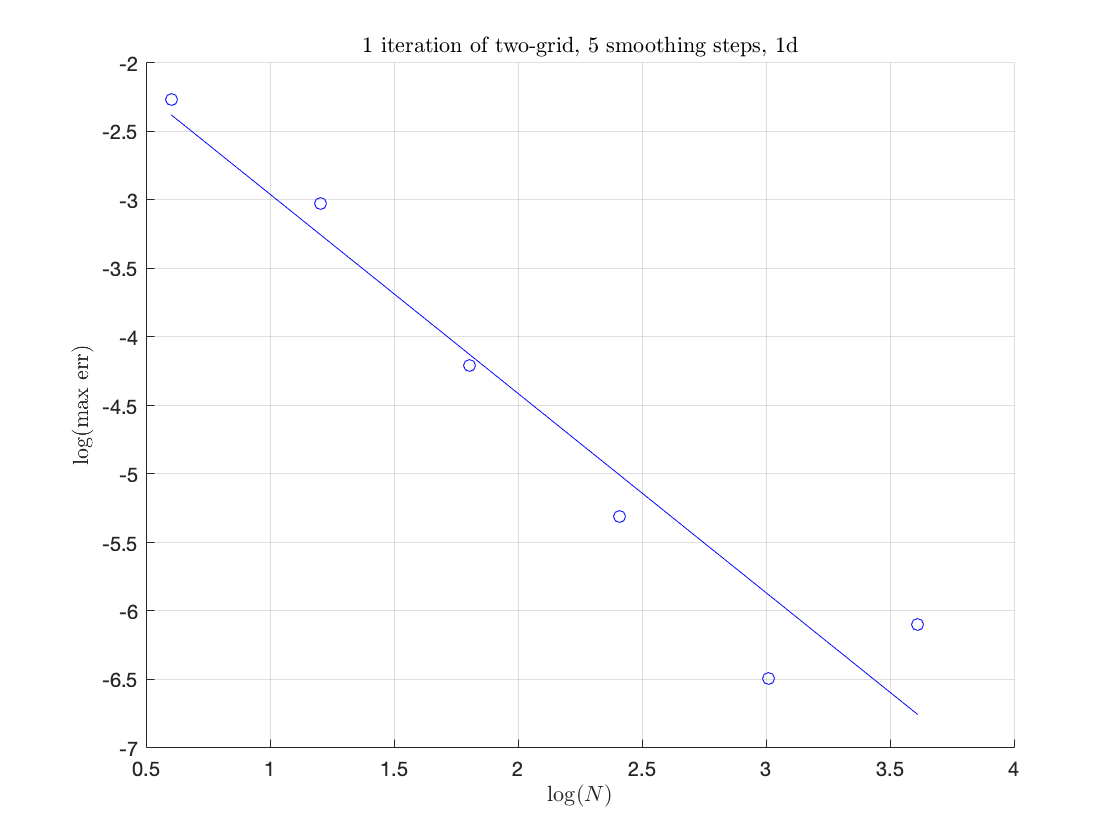

err_decay_rate =    1.454224737584421


Ns = [4,16,64,256,1024,4096];
hs = 2./Ns;
errs = [0.005411301068307, 9.371145547439549e-04, 6.147787540554525e-05, 4.889833527646264e-06, 3.221963287322391e-07, 7.992381019991668e-07];
plotfun(Ns,errs)

function [] = plotfun(Ns,es)
    figure
    hold on

    Bp_es = polyfit(log10(Ns), log10(es), 1);
    Yp_es = polyval(Bp_es,log10(Ns));
    
    plot(log10(Ns), log10(es), 'ob')
    
    title(sprintf('1 iteration of two-grid, 5 smoothing steps, 1d'), 'interpreter', 'latex')
    xlabel('$\log(N)$', 'interpreter', 'latex')
    ylabel('$\log$(max err)', 'interpreter', 'latex')
    
    plot(log10(Ns), Yp_es, '-b')
    hold off
    grid
    err_decay_rate = -Bp_es(1)
end